# Phys 434 Lab 6

## Natalie Shen

### Collaborators: Taylor Prewitt, Francesca Bennet

clear all; close all; clc

h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');

h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

## Problem 1

The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

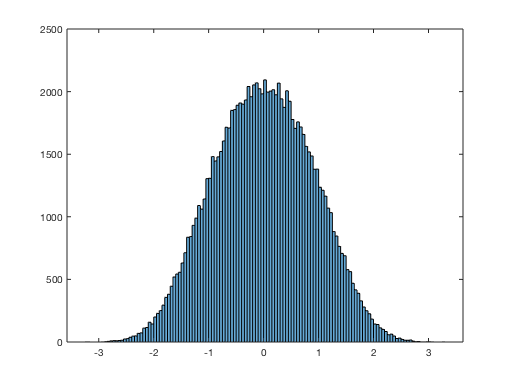

data = higg(2,:);
histogram(data);

m = mean(data);
s = normpdf(data,m,1)

s =     0.3952    0.3987    0.3925    0.3864    0.0635    0.0973    0.0420    0.1171    0.2277    0.2232    0.3400    0.3988    0.2882    0.3953    0.2959    0.3269    0.3911    0.1520    0.3455    0.3910    0.1962    0.3193    0.1650    0.3988    0.2501    0.2215    0.1675    0.2370    0.2491    0.3869    0.0941    0.2990    0.2646    0.3805    0.1787    0.3225    0.2559    0.2952    0.3846    0.3823    0.3634    0.3961    0.3504    0.3812    0.3257    0.3642    0.0728    0.3846    0.2385    0.3847



%probability for sigma 5 is 1 out of 3.5 million
s5p=1/(3.5 * 10.^6);

v = icdf("poisson",1-s5p,100)

v = 154

## Problem 2

Now create a set of injected (simulated) signals of a *single strength*. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.

### a)

 Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

### b)

Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

## Problem 3

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). 

### a)

Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal

### b)

If you choose the same injected signal power as in problem 2, show that you get the same answer.

### c)

Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.

### d)

Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.

### e)

Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?

## Problem 4

Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).

### a)

Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.

### b)

 Describe what it means to have the true signal pdf() extend to zero.

### c)

Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than *X* 95% of the time.]